clear
close
clc

syms x alpha beta real

n = 10

n = 10


P = JacobiPolynomialsSym(alpha,beta,n,x)


ChebyshevTPoly = simplify(subs(P,[alpha beta], [-1/2 -1/2])./subs(P,[alpha beta x], [-1/2 -1/2 1]))'

$$ChebyshevTPoly = \left(\begin{array}{c} 1\\ x\\ 2\,x^{2}-1\\ x\,\left(4\,x^{2}-3\right)\\ 8\,x^{4}-8\,x^{2}+1\\ x\,\left(16\,x^{4}-20\,x^{2}+5\right)\\ 32\,x^{6}-48\,x^{4}+18\,x^{2}-1\\ x\,\left(64\,x^{6}-112\,x^{4}+56\,x^{2}-7\right)\\ 128\,x^{8}-256\,x^{6}+160\,x^{4}-32\,x^{2}+1\\ x\,\left(256\,x^{8}-576\,x^{6}+432\,x^{4}-120\,x^{2}+9\right)\\ 512\,x^{10}-1280\,x^{8}+1120\,x^{6}-400\,x^{4}+50\,x^{2}-1 \end{array}\right)$$

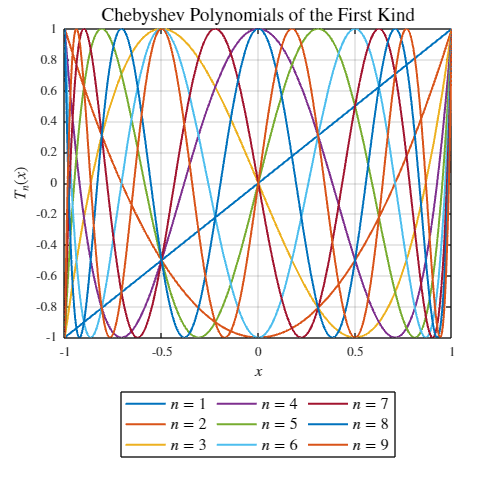

set(groot,"defaultAxesTickLabelInterpreter","latex")
set(groot,"defaultTextInterpreter","latex")
set(groot,"defaultLegendInterpreter","latex")

figure("Position",[100 100 600 600])
box on;
grid on;
hold on;
axis tight;
xlabel("$x$","FontSize",12)
ylabel("$T_n(x)$","FontSize",12)
title("Chebyshev Polynomials of the First Kind","FontSize",14)

for i = 2:n
    fplot(ChebyshevTPoly(i),[-1 1],LineWidth=1.5)
end

legends = cell(1, n-1);
for i = 1:n-1
    legends{i} = sprintf('$n = %d$',i);
end

legend(legends, 'Location', 'southoutside', 'NumColumns', 3,'FontSize',12);